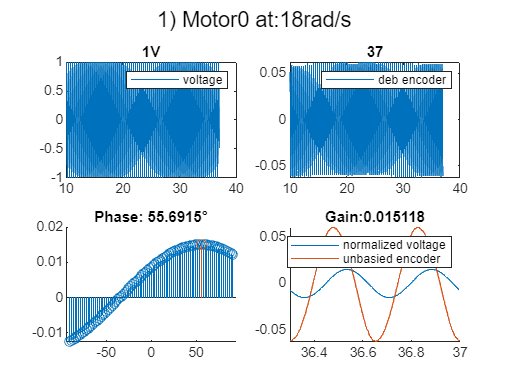

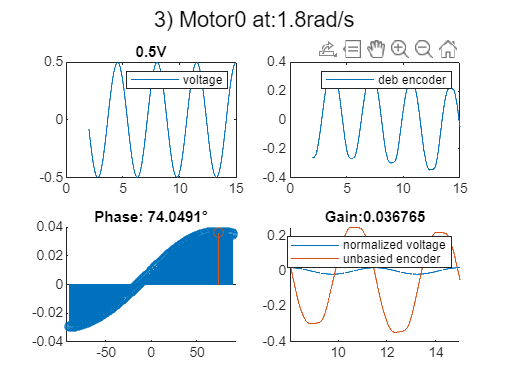

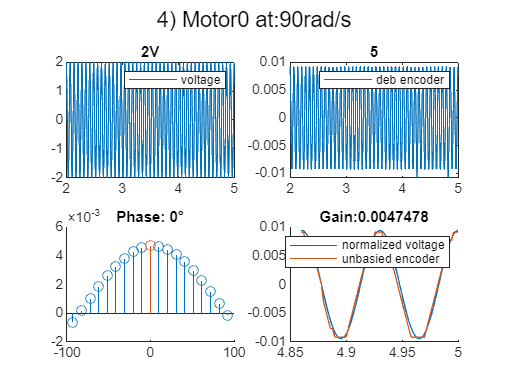

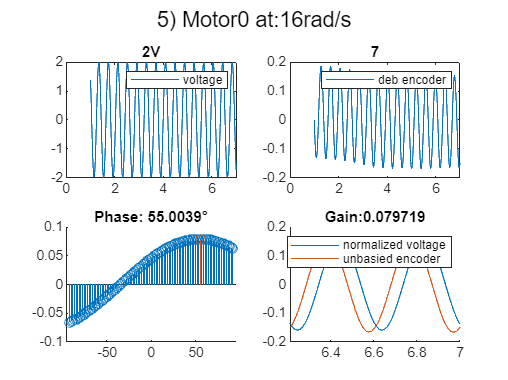

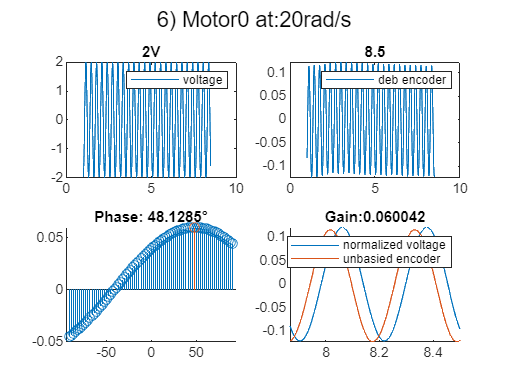

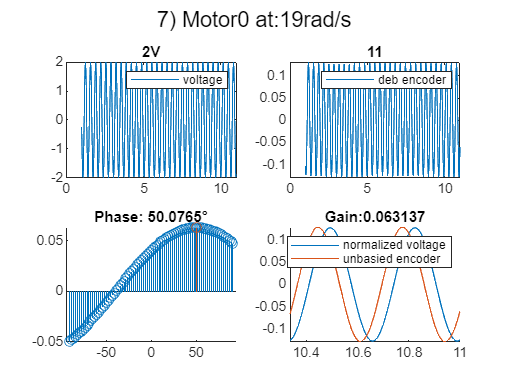

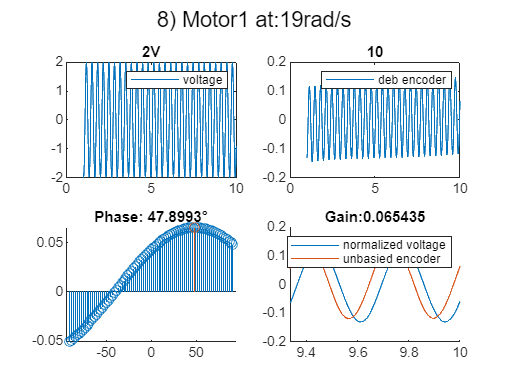

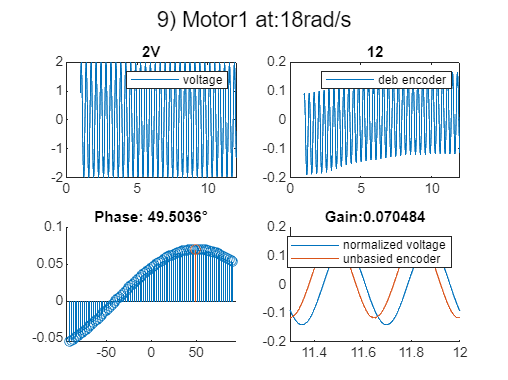

filelist =["data_11-Mar-2025_14-37-46.mat" "data_11-Mar-2025_14-41-45.mat" "data_11-Mar-2025_15-16-40.mat" "data_11-Mar-2025_15-19-03.mat" "data_11-Mar-2025_15-40-23.mat" "data_11-Mar-2025_15-41-07.mat" "data_11-Mar-2025_15-52-28.mat" "data_11-Mar-2025_15-54-11.mat" "data_11-Mar-2025_15-59-13.mat" "data_11-Mar-2025_16-01-46.mat" "data_11-Mar-2025_16-03-02.mat" "data_11-Mar-2025_16-04-30.mat" "data_11-Mar-2025_16-06-17.mat" "data_11-Mar-2025_16-11-48.mat" "data_11-Mar-2025_16-13-05.mat" "data_11-Mar-2025_16-14-08.mat" "data_11-Mar-2025_16-15-13.mat" "data_11-Mar-2025_16-16-28.mat" "data_11-Mar-2025_16-17-45.mat" "data_11-Mar-2025_16-19-12.mat" "data_11-Mar-2025_16-22-06.mat" "data_11-Mar-2025_16-46-42.mat" "data_11-Mar-2025_16-49-20.mat" "data_11-Mar-2025_18-02-55.mat" "data_11-Mar-2025_18-09-05.mat" "data_11-Mar-2025_18-19-48.mat" "data_11-Mar-2025_18-21-25.mat" "data_11-Mar-2025_18-23-27.mat" "data_11-Mar-2025_18-24-00.mat" "data_11-Mar-2025_18-25-32.mat" "data_11-Mar-2025_18-26-22.mat" "data_11-Mar-2025_18-28-35.mat" "data_11-Mar-2025_18-29-53.mat" "data_11-Mar-2025_18-31-38.mat" "data_11-Mar-2025_18-34-32.mat" "data_11-Mar-2025_18-38-31.mat" "data_11-Mar-2025_18-40-21.mat" "data_11-Mar-2025_18-42-37.mat" "data_11-Mar-2025_18-43-54.mat" "data_11-Mar-2025_18-45-12.mat" "data_11-Mar-2025_18-47-03.mat" "data_11-Mar-2025_18-49-24.mat" ];
fs = 500;
ts = 1/fs;
n_exp = 14;
id_exp = 6:21;
motors = [ 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1];

exp_enable = [1 0 1 1 1 1 1 1 1 1 1 1 1 0 1 1];
t_start_v = [ 10 1 2 2 1 1 1 1 1 1 1 1 1 1 1 4];
t_end_v = [37 2 15 5 7 8.5 11 10 12 10 9.5 17 17 2 4.5 9];

ph = [];
G = [];
freqs = [];

% for i = 9:9
for i = 1:size(id_exp,2)
if exp_enable(i)==1
    n_exp = id_exp(i);

    motor_id = motors(i);

    load("lab2/data/"+filelist(n_exp),"data");
    


    omega = data(6,1);
    T = 2*pi/omega;
    Fv = 1/T;
    max_samples_per_period = ceil(T/ts);
    
    angular_resolution = 360/max_samples_per_period;
    maxlag_n = ceil(max_samples_per_period/4);


    Amp = data(7,1);
    t_start = t_start_v(i);
    t_start_idx = 1 + t_start/ts;
    t_end = t_end_v(i);
    t_end_idx = 1 + t_end/ts;

    Tfocus = t_end -t_start;

    t = data(1,t_start_idx:t_end_idx);
    % enc0 = data(2,t_start_idx:end)*pi/2048;
    % u0 = data(4,t_start_idx:end);
    % enc1 = data(3,t_start_idx:end)*pi/2048;
    % u1 = data(5,t_start_idx:end);
    u = data(4+motor_id,t_start_idx:t_end_idx);
    y = data(2+motor_id,t_start_idx:t_end_idx)*pi/2048;
    
    %% DEBIAS
    
    Integ = trapz(t,y);
    b = Integ/Tfocus;
    y_deb = y - b;
    
    [c,lags] = xcorr(u,y,maxlag_n,'biased' );
    c = c/2;

     [c_max, cmaxid] = max(c);
    focus_window = max_samples_per_period*2;
    
    maxlag_time = (2*maxlag_n + 1) * ts;
    lags_time = lags * ts;
    lags_rad = lags_time * 2 * pi / T;
    G(end+1) = c_max;
    ph(end+1) = lags_rad(cmaxid);
    
    freqs(end+1) = omega;
    
    figure
    subplot(2,2,1)
    sgtitle(i+") Motor"+motor_id + " at:" + omega + "rad/s")
    plot(t,u)
    legend("voltage")
    title(Amp+"V")

    subplot(2,2,2)
    plot(t,y_deb)
    title(t(end))
    legend("deb encoder")


    subplot(2,2,4)
    title("Gain:" + c_max)
    hold on
    plot(t(end-focus_window:end),c_max*u(end-focus_window:end))
    plot(t(end-focus_window:end),y_deb(end-focus_window:end))
    hold off
    legend(["normalized voltage","unbasied encoder"])


    subplot(2,2,3)
    title("Phase: " + rad2deg(lags_rad(cmaxid)) + "°")
    hold on
    stem(lags*angular_resolution,c)
    stem(rad2deg(lags_rad(cmaxid)),c_max)
    hold off
end
end

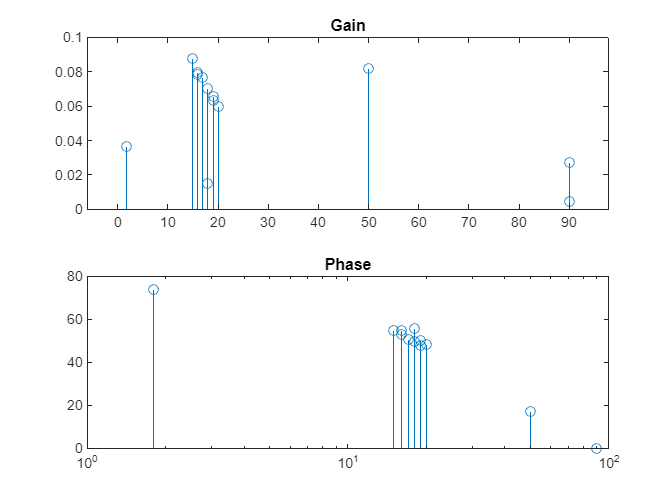


figure
subplot(2,1,1)
stem(freqs,G)
title("Gain")
subplot(2,1,2)
stem(freqs,rad2deg(ph))
xscale("log")
title("Phase")



% 
% figure
% hold on;
% plot(t,u0)
% plot(t,u1)
% legend(["Motor 0","Motor 1"])
% title("Voltage signal")
% hold off
% 
% figure
% hold on
% plot(t,enc0)
% plot(t,enc1)
% legend(["Motor 0","Motor 1"])
% title("Encoder position")
% hold off


% [c,lags] = xcorr(u1,enc1,ceil(max_samples_per_period/2),'biased');
% lags_angle = lags * 360/max_samples_per_period;
% c = c/2;
% [c_max, idx_max] = max(c);
% angle_max = -180 + (idx_max-1) * 360/max_samples_per_period;
% 
% [c_min, idx_min] = min(c);
% angle_min = (idx_min-1) * 360/max_samples_per_period;
% 
% 
% figure
% hold on;
% stem(lags_angle,c)
% stem(angle_max,c_max,'filled')
% stem(-180+angle_min,c_min,'filled')
% 
% 
% 
% hold off;
% title("CrossCorrelation, test at "+omega+"rad/s")
% subtitle("Peak at:" + (angle_min+angle_max)/2 +"° Gain:" + c_max)

% t_end = t(1,end);
% 
% A = [];
% ph = [];
% 
% for i=1:1
%     tf_start_idx = t_start_idx
%     tf_end_idx = t_end_idx ;
%     t_focus = t(tf_start_idx:tf_end_idx) ;  
%     y_focus = enc1(tf_start_idx:tf_end_idx) ; 
%     u_focus = u1(tf_start_idx:tf_end_idx) ; 
% 
%     %% debias
%     Integ = trapz(t_focus,y_focus);
%     b = Integ/T;
% 
% 
%     y_deb = y_focus - b;
% 
%        %% cross corr
% 
% 
%     max_samples_per_period = ceil(T/ts);
%     maxlag_n = ceil(max_samples_per_period/4) ;% just +-90° per side
%     [c,lags] = xcorr(u_focus,y_focus,maxlag_n,'biased' );
%     c_deb = xcorr(u_focus,y_deb,maxlag_n,'biased' );
% 
%     norm_factor =  2;
%     c = c/norm_factor;
%     c_deb = c_deb/norm_factor;
% 
%     [c_max, cmaxid] = max(c);
%     [c_deb_max, c_deb_max_id] = max(c_deb);
% 
% 
%     maxlag_time = (2*maxlag_n + 1) * ts;
%     lags_time = lags * ts;
%     lags_angle = lags_time * 360 / T;
% 
%         if i == 10
%         figure
%         hold on
%         plot(t_focus,y_focus);
%         plot(t_focus,y_deb);
%         legend(["original","debiased"])
%         hold off
% 
%         figure
%         hold on
%         stem(lags_angle,c)
%         stem(lags_angle,c_deb)
%         stem(lags_angle(cmaxid),c_max)
%         stem(lags_angle(c_deb_max_id),c_deb_max)
%         title("XCorr with ideal sinusoids")
%         legend(["raw", "debiased","peak raw","peak debiased"], "Position", [0.5543 0.2845 0.3035, 0.1142])
%         hold off;
% 
%         A(end+1) = c_deb_max
% 
%         ph(end+1) = lags_angle(c_deb_max_id)
% 
% 
%         figure
%         hold on
%         plot(t_focus,u_focus*c_deb_max);
%         plot(t_focus,y_deb);
%         legend(["voltage","encoder"])    
%         hold off
%         end
% end
% 
% mean(A)
% mean(ph)
